# 4 Biomedical Data

set(groot, 'defaultAxesFontSize',15);

% Preprocess data
[hnormal] = importdata("files_lab7\hnormal.txt");
[hslow] = importdata("files_lab7\hslow.txt");
hnormal_prepped = detrend(hnormal.data);
hslow_prepped = detrend(hslow.data);
f_s = 100;
[a, b] = butter(30, 40/(f_s/2));
hnormal_prepped = filter(a,b,hnormal_prepped);
hslow_prepped = filter(a,b,hslow_prepped);

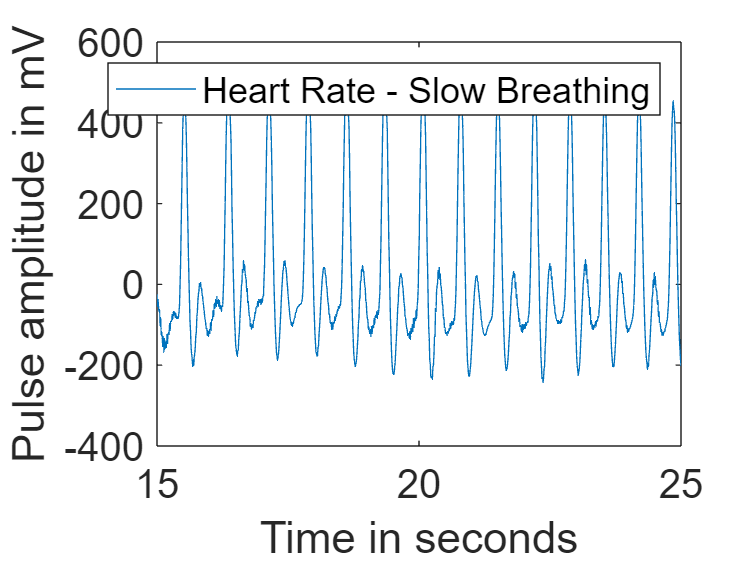

t = linspace(15, 25, 10*f_s);
t_resp = linspace(10, 30, 20*f_s);
hr_slow = hslow_prepped(:, 6);
hr_normal = hnormal_prepped(:, 6);

% plot(t, hr_normal(15*f_s:25*f_s-1));
% hold on
plot(t, hr_slow(15*f_s:25*f_s-1));
hold off
ylabel("Pulse amplitude in mV")
xlabel("Time in seconds");
legend("Heart Rate - Slow Breathing");

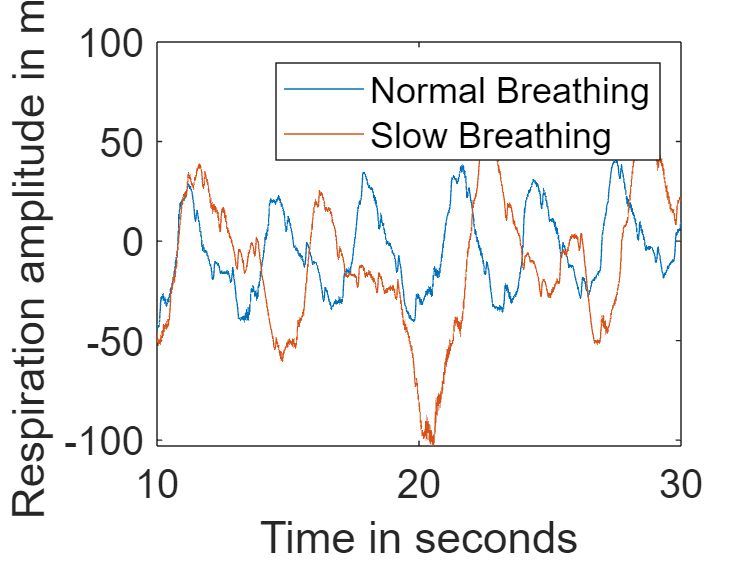


resp_slow = hslow_prepped(:, 7);
resp_normal = hnormal_prepped(:, 7);
plot(t_resp, resp_normal(10*f_s:30*f_s-1), t_resp, resp_slow(10*f_s:30*f_s-1));
ylabel("Respiration amplitude in mV")
xlabel("Time in seconds");
legend(["Normal Breathing", "Slow Breathing"]);

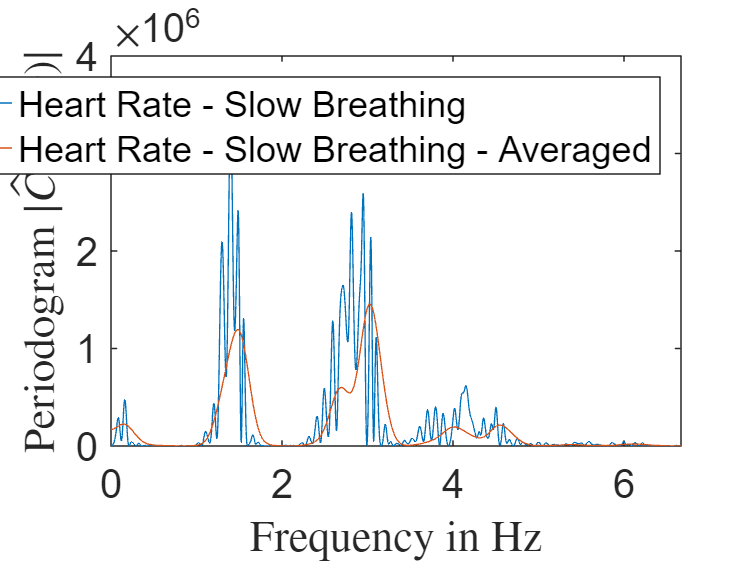

% Periodograms and Averaged Periodograms
hr_slow_tr = hr_slow(460:3603);
hr_normal_tr = hr_normal(460:3603);
resp_normal_tr = resp_normal(460:3603);
resp_slow_tr = resp_slow(460:3603);

w_biom = linspace(0, f_s, 10*length(hr_slow_tr));
w_biom_av = linspace(0, f_s, 10*length(hr_slow_tr)/6);

% hr_slow
p_hr_slow = spec1_zp(hr_slow_tr, 1, hamming(length(hr_slow_tr)));
p_hr_slow_av = spec1_zp(hr_slow_tr, 6, hamming(length(hr_slow_tr)/6));

plot(w_biom, p_hr_slow, w_biom_av, p_hr_slow_av);
xlim([0, f_s/15]);
legend(["Heart Rate - Slow Breathing", "Heart Rate - Slow Breathing - Averaged"]);
xlabel("Frequency in Hz", 'interpreter', 'latex');
ylabel("Periodogram $|\hat{C}(e^(jw)|$", 'interpreter', 'latex');

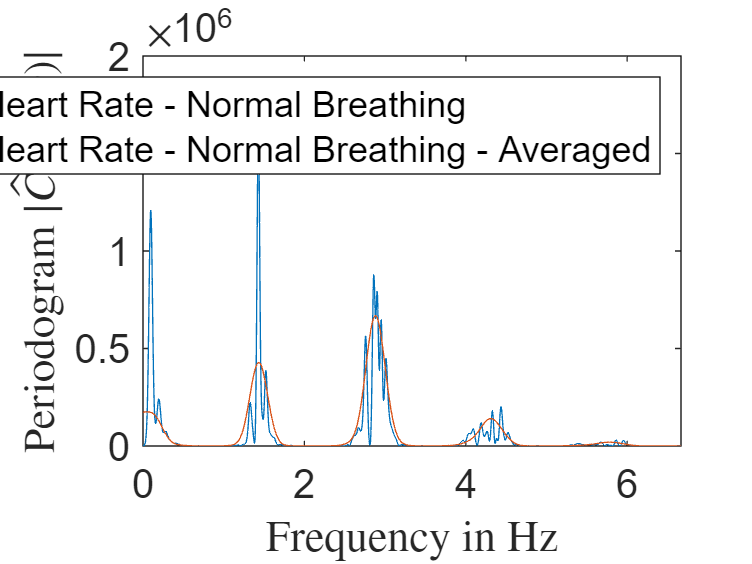


% hr_normal
p_hr_normal = spec1_zp(hr_normal_tr, 1, hamming(length(hr_normal_tr)));
p_hr_normal_av = spec1_zp(hr_normal_tr, 6, hamming(length(hr_normal_tr)/6));

plot(w_biom, p_hr_normal, w_biom_av, p_hr_normal_av);
xlim([0, f_s/15]);
legend(["Heart Rate - Normal Breathing", "Heart Rate - Normal Breathing - Averaged"]);
xlabel("Frequency in Hz", 'interpreter', 'latex');
ylabel("Periodogram $|\hat{C}(e^(jw)|$", 'interpreter', 'latex');

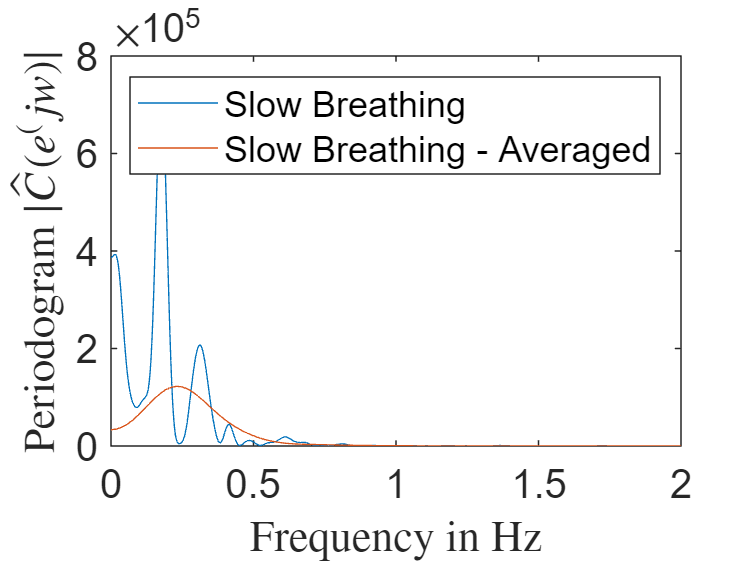


% resp_slow
p_resp_slow = spec1_zp(resp_slow_tr, 1, hamming(length(resp_slow_tr)));
p_resp_slow_av = spec1_zp(resp_slow_tr, 6, hamming(length(resp_slow_tr)/6));

plot(w_biom, p_resp_slow, w_biom_av, p_resp_slow_av);
xlim([0, f_s/50]);
legend(["Slow Breathing", "Slow Breathing - Averaged"]);
xlabel("Frequency in Hz", 'interpreter', 'latex');
ylabel("Periodogram $|\hat{C}(e^(jw)|$", 'interpreter', 'latex');

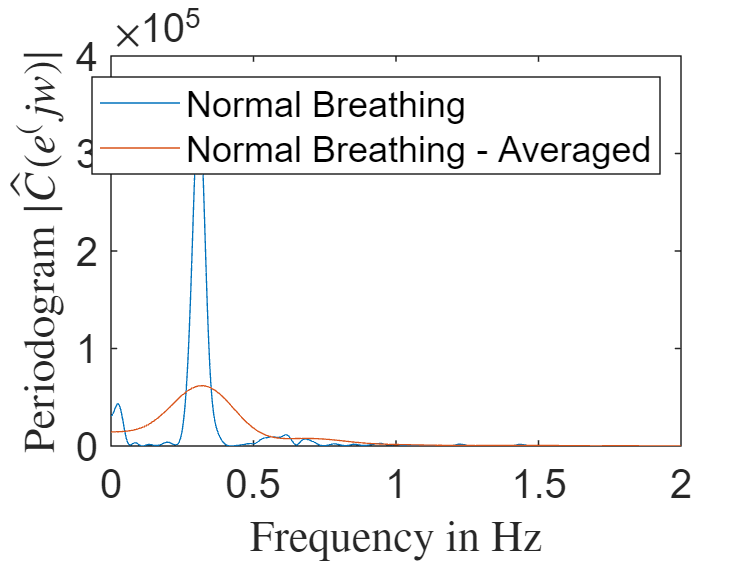


% resp_normal
p_resp_normal = spec1_zp(resp_normal_tr, 1, hamming(length(resp_normal_tr)));
p_resp_normal_av = spec1_zp(resp_normal_tr, 6, hamming(length(resp_normal_tr)/6));

plot(w_biom, p_resp_normal, w_biom_av, p_resp_normal_av);
xlim([0, f_s/50]);
legend(["Normal Breathing", "Normal Breathing - Averaged"]);
xlabel("Frequency in Hz", 'interpreter', 'latex');
ylabel("Periodogram $|\hat{C}(e^(jw)|$", 'interpreter', 'latex');

% Estimates for the heart rate and the respiration